# Anti-aliasing Filter

Copyright (C) 2021 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

## Introduction 

This notebook provides introduction to a model for an anti-aliasing filter. 

Aliasing occurs when high and low frequency samples are indistinguishable thus resulting in improper conversion of the input signal. According to the Nyquist criterion, the sampling rate should be at least twice the maximum frequency component of the signal. Aliasing usually exists when Nyquist criterion is violated and should be prevented through the use of low-pass (anti-aliasing) filters. These low pass filters are added before the sampler and the ADC. 

The goal is to model an anti-alias filter that attenuates the higher frequencies (higher than the Nyquist frequency) which would prevent the aliasing components from being sampled.

## Antialiasing example

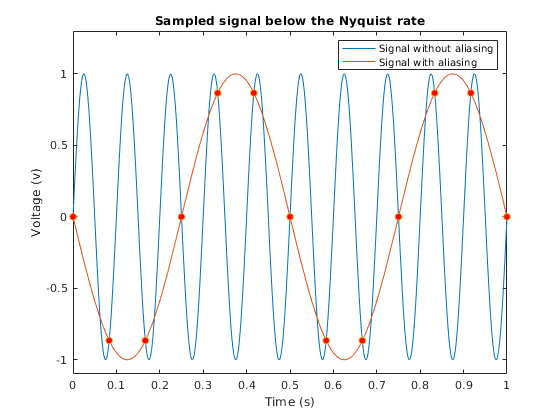

clear all
fs=12;
fsine=10;
Ts=1/fs;
t=0:0.001:1; %time;
y=sin(2*pi*fsine*t);
n=0:fs;
ys=sin(2*pi*fsine*Ts*n);
figure
plot(t,y)
hold on
falias=-mod(fs,fsine); % modify this line for different sampling frequencies than 12Hx
plot(t, sin(2*pi*falias*t)) 
plot(Ts*n, ys, 'o',  'MarkerFaceColor', 'r')


legend (["Signal without aliasing", "Signal with aliasing"])
title('Sampled signal below Nyquist rate')
xlabel('Time (s)')
ylabel('Voltage (v)')
ylim([-1.1, 1.3])

## Anti-aliasing Filter Model

The following simple model was created to model an analog anti-aliasing filter. Since it is before the sampler and the ADC this is the analog world and the anti-aliasing filter is an analog filter. An input voltage is confiured here and and the results will be plotted as a sampled signal with and without antialiasing filter. 

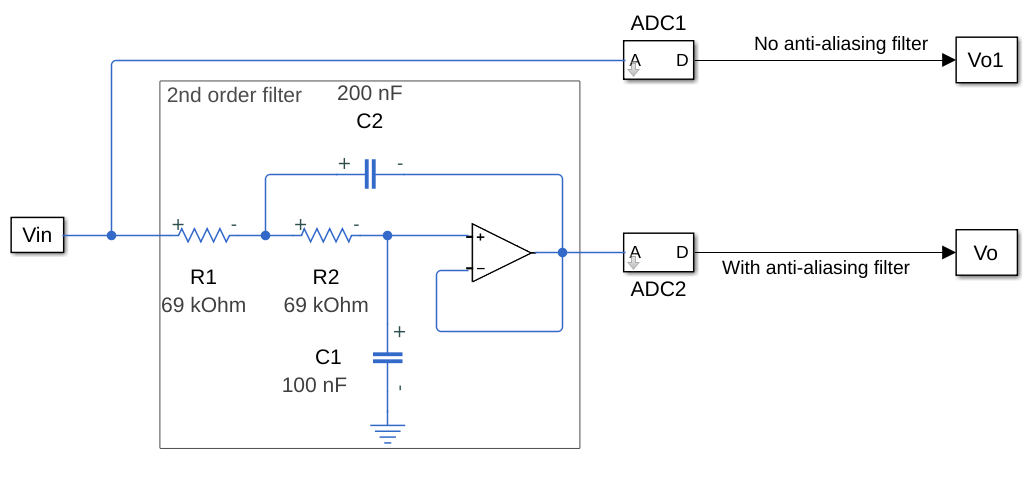

### Configure Input 

The input voltage is configured here as a sin function. The reshape function is included as it can be helpful for preprocessing the data for subsequent computations or analyzing the data.

model_name = 'elec_a2d_sd_anti_alias_graph';
open_system(model_name);


T=0.001; 
Vin(:,1)=0:T:60; %time;
t=Vin(:,1); Vin(:,2)=1.5+sin(2*pi*0.25*t)+0.25*sin(2*pi*60*t);
sim(model_name)
simOut = sim('elec_a2d_sd_anti_alias_graph', 'CaptureErrors', 'on');
temp=simOut.vOut.signals.values(:,1,:);
alias=reshape(temp,4801,1);
temp=simOut.vOut.signals.values(:,2,:);
no_alias=reshape(temp,4801,1);

### Plot Sampled Signal 

The time domain signal is plotted here. 

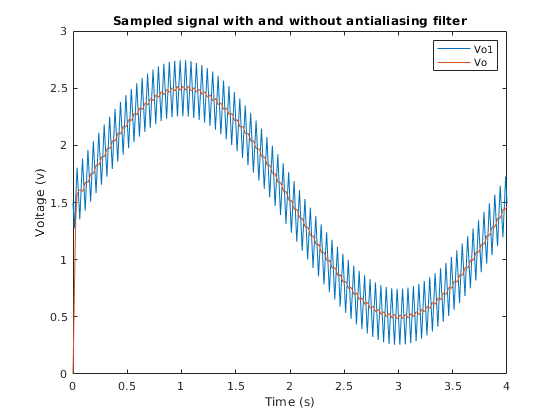

figure
plot(simOut.vOut.time,alias)
hold on
plot(simOut.vOut.time,no_alias)
xlim([0,4])
legend (["Vo1", "Vo"])
title('Sampled signal with and without antialiasing filter')
xlabel('Time (s)')
ylabel('Voltage (v)')

### Plot amplitude response

fs=80;
L=length(no_alias)-1;
n = 2^nextpow2(L);


Compute the two-sided spectrum `P2`. Then compute the single-sided spectrum `P1` based on `P2` and the even-valued signal length `L`.

Y = fft(alias,n);
P2a = abs(Y/n);
P1a = P2a(1:n/2+1);
P1a(2:end-1) = 2*P1a(2:end-1);

Y = fft(no_alias,n);
P2n = abs(Y/n);
P1n = P2n(1:n/2+1);
P1n(2:end-1) = 2*P1n(2:end-1);

Define the frequency domain `f` and plot the single-sided amplitude spectrum `P1`. The amplitudes are not exactly at 0.7 and 1, as expected, because of  the added noise. On average, longer signals produce better frequency  approximations.

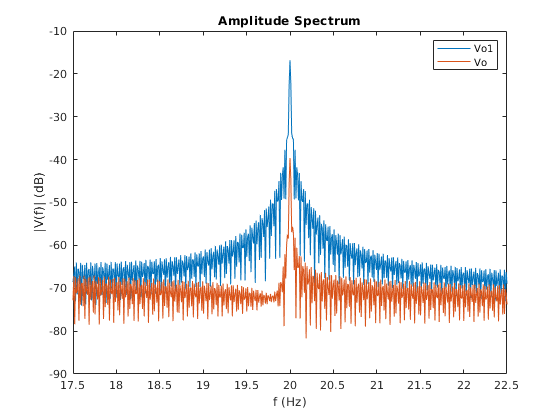

f = fs*(0:(n/2))/n;
figure
plot(f,mag2db(P1a)) 
hold on
plot(f,mag2db(P1n)) 
title('Amplitude Spectrum')
xlabel('f (Hz)')
ylabel('|V(f)| (dB)')
ylim([-90  , -10])
xlim([17.5, 22.5])
legend (["Vo1", "Vo"])